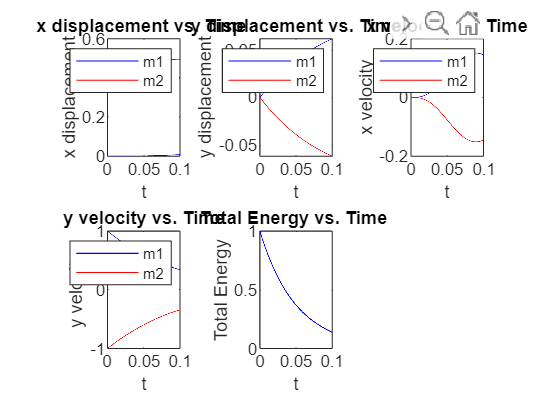

% Define system parameters
m1 = 1.0;       % Mass of m1 in kg
m2 = 1.0;       % Mass of m2 in kg
k = 1000.0;     % Spring stiffness in N/m
c = 5.0;        % Damping coefficient in Ns/m
l = 0.5;      % Free length of the spring in m
g = 0;     % Acceleration due to gravity in m/s^2

% Initial conditions
x1_i = 0.0;
y1_i = 0.0;
vx1_i = 0.0;
vy1_i = 1.0;

x2_i = 0.5;
y2_i = 0.0;
vx2_i = 0.0;
vy2_i = -1.0;

% Time step
dt = 1.0e-5;

% Number of time steps
num_steps = 10000;

% Time array
time = (0:num_steps-1) * dt;

% Initialize arrays to store positions and velocities
x1 = zeros(1, num_steps);
y1 = zeros(1, num_steps);
vx1 = zeros(1, num_steps);
vy1 = zeros(1, num_steps);

x2 = zeros(1, num_steps);
y2 = zeros(1, num_steps);
vx2 = zeros(1, num_steps);
vy2 = zeros(1, num_steps);

% Initialize distance between masses array
distance_between_masses = zeros(1, num_steps);

% Initialize kinetic energy, spring potential energy, gravitational potential energy and total energy array
kinetic_energy = zeros(1, num_steps);
spring_pot_energy = zeros(1, num_steps);
grav_pot_energy = zeros(1, num_steps);
total_energy = zeros(1, num_steps);

% Set initial conditions
x1(1) = x1_i;
y1(1) = y1_i;
vx1(1) = vx1_i;
vy1(1) = vy1_i;

x2(1) = x2_i;
y2(1) = y2_i;
vx2(1) = vx2_i;
vy2(1) = vy2_i;

distance_between_masses(1) = sqrt((x2(1) - x1(1))^2 + (y2(1) - y1(1))^2);
kinetic_energy(1) = 0.5*m1*((vx1(1))^2 + (vy1(1))^2) + 0.5*m2*((vx2(1))^2 + (vy2(1))^2);
spring_pot_energy(1) = 0.5*k*((distance_between_masses(1) - l)^2);
grav_pot_energy(1) = m1*g*y1(1) + m2*g*y2(1);
total_energy(1) =  kinetic_energy(1) + spring_pot_energy(1) + grav_pot_energy(1);

% disp(total_energy(1));

% Using Euler's explicit scheme
for i = 1:num_steps-1
    % Forces
    spring_force = k * (distance_between_masses(i) - l);
    damper_force_x = c * (vx2(i) - vx1(i));
    damper_force_y = c * (vy2(i) - vy1(i));
    
    % Accelerations
    ax1 = (spring_force * (x2(i) - x1(i))) / (m1 * distance_between_masses(i)) + damper_force_x / m1;
    ay1 = (spring_force * (y2(i) - y1(i))) / (m1 * distance_between_masses(i)) + damper_force_y / m1 - g;
    
    ax2 = (spring_force * (x1(i) - x2(i))) / (m2 * distance_between_masses(i)) - damper_force_x / m2;
    ay2 = (spring_force * (y1(i) - y2(i))) / (m2 * distance_between_masses(i)) - damper_force_y / m2 - g;
    
    % Update velocities and positions of m1
    vx1(i+1) = vx1(i) + ax1 * dt;
    vy1(i+1) = vy1(i) + ay1 * dt;
    
    x1(i+1) = x1(i) + vx1(i+1) * dt;
    y1(i+1) = y1(i) + vy1(i+1) * dt;
    
    % Update velocities and positions of m2
    vx2(i+1) = vx2(i) + ax2 * dt;
    vy2(i+1) = vy2(i) + ay2 * dt;
    
    x2(i+1) = x2(i) + vx2(i+1) * dt;
    y2(i+1) = y2(i) + vy2(i+1) * dt;

    % Update distance
    distance_between_masses(i+1) = sqrt((x2(i+1) - x1(i+1))^2 + (y2(i+1) - y1(i+1))^2);

    % Update energy
    kinetic_energy(i+1) = 0.5*m1*((vx1(i+1))^2 + (vy1(i+1))^2) + 0.5*m2*((vx2(i+1))^2 + (vy2(i+1))^2);
    spring_pot_energy(i+1) = 0.5*k*((distance_between_masses(i+1) - l)^2);
    grav_pot_energy(i+1) = m1*g*y1(i+1) + m2*g*y2(i+1);
    total_energy(i+1) =  kinetic_energy(i+1) + spring_pot_energy(i+1) + grav_pot_energy(i+1);
end

for i = 1:num_steps
    kinetic_energy(i) = round(kinetic_energy(i), 3);
    spring_pot_energy(i) = round(spring_pot_energy(i), 3);
    grav_pot_energy(i) = round(grav_pot_energy(i), 3);
    total_energy(i) = round(total_energy(i), 3);
end

% Plot results in 1 plot
figure;

% x vs time plot
subplot(2,3,1);
plot(time, x1, 'b',time,x2,'r');
xlabel('t');
ylabel('x displacement');
legend('m1', 'm2');
title('x displacement vs. Time ');

% y vs time plot
subplot(2,3,2);
plot(time, y1, 'b',time,y2,'r');
xlabel('t');
ylabel('y displacement');
legend('m1', 'm2');
title('y displacement vs. Time');

% vx vs time plot
subplot(2,3,3);
plot(time, vx1, 'b',time,vx2,'r');
xlabel('t');
ylabel('x velocity');
legend('m1', 'm2');
title('x velocity vs. Time');

% vy vs time plot
subplot(2,3,4);
plot(time, vy1, 'b',time,vy2,'r');
xlabel('t');
ylabel('y velocity');
legend('m1', 'm2');
title('y velocity vs. Time');

% Energy vs time plot
subplot(2,3,5);
plot(time, total_energy, 'b');
xlabel('t');
ylabel('Total Energy');
title('Total Energy vs. Time ');